# Week 1 Demo - defining variables, plotting, introduction to matrices

This week, we will introduce the basics of MATLAB.  It is important to have some fundamentals of syntax and good coding practice solidifed before we begin to solve ODEs numerically.  

## Defining variables

MATLAB is a powerful tool used by mathematicians, engineers, physicists, etc. to solve a wide away of quantitiative problems.  The way you define variables and use them is somewhat intuitive.  Let's start by defining a variable $c=3$, and let's see what happens if we square *c, *and assign the result to variable $d$.  

c = 3

c = 3

d = c^2

d = 9

These quantities are **scalars**.  We will also work very often with **vectors, **which in many cases simply represent individual points uniformly selected over an interval.  For example, let us create a vector-valued quantity $x$ to be a vector with 100 evenly-spaced points between -5 and 5.  

x = linspace(-5,5)

x =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


Notice the structure of this variable.  Throughout this course, it will be very important to keep track of which variables are scalars and which are vectors.  As you learned in Calc 3, you can multiply scalars and vectors together as so:

c*x

ans =   -15.0000  -14.6970  -14.3939  -14.0909  -13.7879  -13.4848  -13.1818  -12.8788  -12.5758  -12.2727  -11.9697  -11.6667  -11.3636  -11.0606  -10.7576  -10.4545  -10.1515   -9.8485   -9.5455   -9.2424   -8.9394   -8.6364   -8.3333   -8.0303   -7.7273   -7.4242   -7.1212   -6.8182   -6.5152   -6.2121   -5.9091   -5.6061   -5.3030   -5.0000   -4.6970   -4.3939   -4.0909   -3.7879   -3.4848   -3.1818   -2.8788   -2.5758   -2.2727   -1.9697   -1.6667   -1.3636   -1.0606   -0.7576   -0.4545   -0.1515


## Plotting $y=x^2$

Now we have defined $x$, which is a **discrete** (i.e. not continuous) representation of the interval [-5,5].  What happens now if we try to define $y=x^2$?  

y = x.^2

y =    25.0000   24.0001   23.0206   22.0615   21.1228   20.2046   19.3067   18.4292   17.5722   16.7355   15.9193   15.1235   14.3480   13.5930   12.8584   12.1442   11.4504   10.7770   10.1240    9.4914    8.8792    8.2874    7.7160    7.1651    6.6345    6.1244    5.6346    5.1653    4.7164    4.2878    3.8797    3.4920    3.1247    2.7778    2.4513    2.1452    1.8595    1.5942    1.3494    1.1249    0.9208    0.7372    0.5739    0.4311    0.3086    0.2066    0.1250    0.0638    0.0230    0.0026


Notice that if we try the syntax used for scalars (y=x^2), we get an error message.  That is because there is no mathematical definition for "squaring" a vector.  However, if we use the syntax (y=x.^2), we get no error message now.  That is because what we really need to do is an **element-wise** operation.  That is, each individual element of the vector is getting squared.  Note that element-wise operations also apply to multiplication and division.  For example, if we want to define $z=xy$, we do the following:

z = x.^y

z = 1.0e+17 *

  -2.9802 + 0.0000i   0.3653 + 0.0001i  -0.0476 - 0.0031i   0.0065 + 0.0013i  -0.0009 - 0.0004i   0.0001 + 0.0001i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


Now, suppose we want to plot $y$ and $z$ versus $x$, label our axes, and add a title.  We do the following:

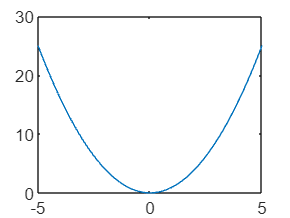

% figure creates an empty figure
plot(x,y)

% hold on this line is necesary to plot multiple curves on the same plot
plot(x,z)

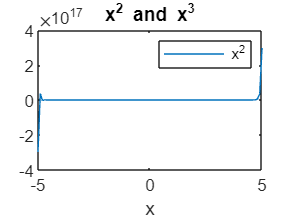

xlabel('x')
title('x^2 and x^3')
legend('x^2','y^2')

Note the use of the "hold on" command.  This is necessary for plotting multiple curves on the same plot.

## Matrices

For specifics on matrix-vector multiplication and solving systems of equations in MATLAB, please refer to the document under module 1 on canvas.  

As the first three letters suggest, MATLAB works heavily with matrices and vectors to enable efficient calculations.  There are some effecient commands for making specific kinds of matrices, and you will get some practice with those in problem 3 of worksheet 1.  Let's suppose we want to make a simple 3 x 3 matrix, we do the following:

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


We will work more in-depth with matrices in the future.  